% electrodeNumsMedia = rawData_cells_D1.rawMap(1).map.electrode(electrodes)
% sortedElectrodeNumsMedia = sort(electrodeNumsMedia);
% 
% subtractedPercentages  = surfaceScanCellsD1.Var2 - surfaceScanCellsT0.Var2;
% subPercentagesTable = table(surfaceScanCellsD1.Var1,subtractedPercentages)
% sortedTable = sortrows(subPercentagesTable);
% 
% memberElectrodes = ismember(sortedTable.Var1,sortedElectrodeNumsMedia)
% 
% percentagesMedia = sortedTable.Var2(memberElectrodes);
% 
% percentagesMedia(end + 1:1012,:) = 99999;
% 
% mappedPercentagesMedia = getMappedElectrodes(percentagesMedia);
% tiledlayout(1,2);
% 
% nexttile;
% 
% heatmap(mappedPercentagesMedia,'ColorLimits',[0 2])
% 
% nexttile;
% 
% electrodeNumsMedia(end + 1:1012,:) = 99999;
% 
% resistancesTableMedia = table(electrodeNumsMedia,unmappedData)
% 
% sortedResistancesTableMedia = sortrows(resistancesTableMedia);
% 
% [heatmapData,unmappedData] = getHeatmap(PSDs_cells_D1-PSDs_cells_T0,freqs);
% heatmap(heatmapData,'ColorLimits',[0 50000]);
% 
% x = table(percentagesMedia,unmappedData)

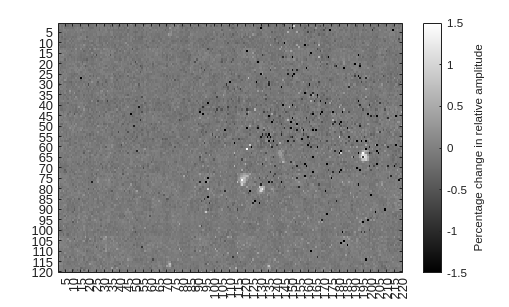




controlCondition = getMappedElectrodes(surfaceScanCellsT0);
 h1 = imagesc((-(getMappedElectrodes(surfaceScanCellsD1)-controlCondition)));
 colormap(gca,"gray");
    
    clim([-1.5,1.5])
    cb = colorbar;
    cb.Label.String = "Percentage change in relative amplitude";
    ax = gca;
    ax.XTick = 0:5:220;
    ax.YTick = 0:5:120;

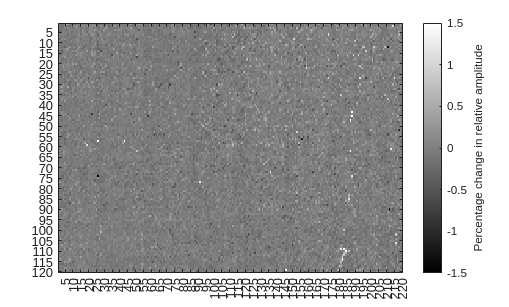


controlCondition = getMappedElectrodes(surfaceScanMediaT0);
 h1 = imagesc((-(getMappedElectrodes(surfaceScanMediaD1)-controlCondition)));
 colormap(gca,"gray");
    
    clim([-1.5,1.5])
    cb = colorbar;
    cb.Label.String = "Percentage change in relative amplitude";
    ax = gca;
    ax.XTick = 0:5:220;
    ax.YTick = 0:5:120;

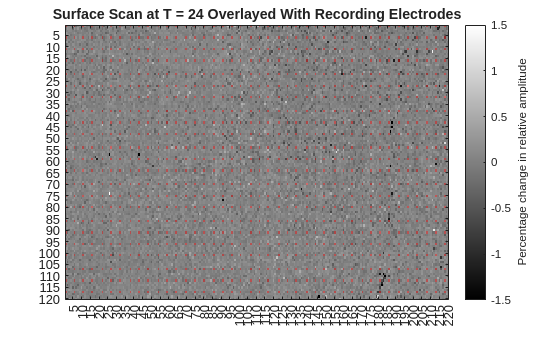


plotOverlayedImage(rawData_media_D1,surfaceScanMediaD1,surfaceScanMediaT0,24);

plotOverlayedImage(rawData_cells_D1,surfaceScanCellsT30,surfaceScanCellsT0,0.5);

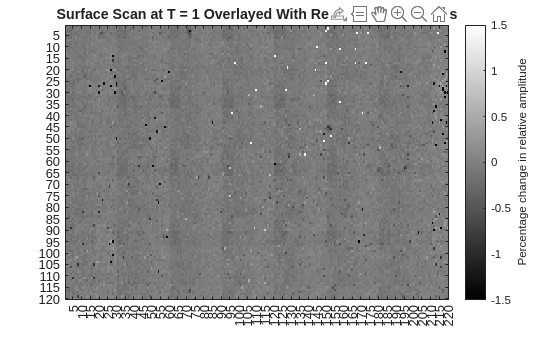

plotOverlayedImage(rawData_cells_D1,surfaceScanCellsT60,surfaceScanCellsT0,1,resistanceCellsT60);

plotOverlayedImage(rawData_cells_D1,surfaceScanCellsD1,surfaceScanCellsT0,24,resistanceCellsD1);

Unrecognized function or variable 'resistanceCellsD1'.

function mappedElectrodes = getMappedElectrodes(electrodesTable)
        
    sortedElectrodesTable = sortrows(electrodesTable);
    electrodeVals = sortedElectrodesTable.Var2;

    mappedElectrodes = zeros([120,220]);
    
    for i = 1:120
        x = (i-1)*220;
        y = i*220;
        mappedElectrodes(i,1:220) = transpose(electrodeVals(x+1:y));
    end
end

function mappedElectrodes = getMappedElectrodeOverlay(electrodes)
        
    mappedElectrodes = zeros([120,220]);
    
    for i = 1:120
        x = (i-1)*220;
        y = i*220;
        mappedElectrodes(i,1:220) = transpose(electrodes(x+1:y));
    end
end

function plotOverlayedImage(rawData,surfaceScanData,controlConditionScanData,T,resistances)

    controlCondition = getMappedElectrodes(controlConditionScanData);

    electrodeNums= rawData.rawMap(1).map.electrode(1:966);
    
    sortedElectrodeNums = sort(electrodeNums+1);
    mappedZeros = (zeros(26400,1));
    mappedZeros(sortedElectrodeNums) = 1;
    mappedElectrodeOverlay = getMappedElectrodeOverlay(mappedZeros);
    
    figure
    h1 = imagesc((getMappedElectrodes(surfaceScanData)-controlCondition));
    colormap(gca,"gray");
    
    clim([-1.5,1.5])
    cb = colorbar;
    cb.Label.String = "Percentage change in relative amplitude";
    ax = gca;
    ax.XTick = 0:5:220;
    ax.YTick = 0:5:120;
    str = 'Surface Scan at T = ' + string(T)+ ' Overlayed With Recording Electrodes';
    
    title(h1.Parent,str);
    
    
    hold on;
    mask = imagesc(resistances);
    colormap(gca,"gray");
   
    %scaledResistances = (resistances-min(resistances(:)))/(max(resistances(:))-min(resistances(:)));
    
    set(mask, 'AlphaData', 0.5* mappedElectrodeOverlay);
    
    mask.CData = cat(3, ones(size(mappedElectrodeOverlay)),zeros(size(mappedElectrodeOverlay)),zeros(size(mappedElectrodeOverlay)));
    hold off;
end